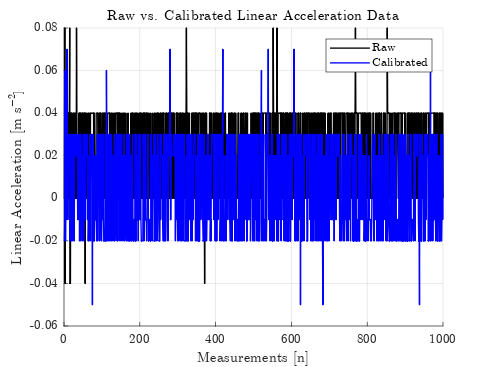

% Read raw and calibrated linear acceleration data
set(0,'defaulttextinterpreter','latex')
AccelData = dlmread('BNO085_linear_accel_data_raw_cal.txt', '\t'); %#ok<DLMRD>
imuAccelData = dlmread('BNO085_linear_accel_data_imu.txt', '\t'); %#ok<DLMRD>
cal_data = dlmread('BNO085_linear_accel_data_cal.txt', '\t'); %#ok<DLMRD>
rawAccelData = AccelData(:,1);
calAccelData = cal_data(:,1);
n = 1:1:length(AccelData);
units = 'm/s^2';
Gray = [.5 .5 .5];
RGB_Violet = [0.4940 0.1840 0.5560];
RGB_Maroon = [0.6350 0.0780 0.1840];
RGB_Yellow = [0.9290 0.6940 0.1250];
RGB_Orange = [0.8500 0.3250 0.0980];
RGB_Forest = [0.4660 0.6740 0.1880];
RGB_Blue = [0 0.4470 0.7410];
target_accel = zeros(length(AccelData), 1);

figure;
hold on
grid on
% plot(n,rawAccelData,LineWidth=0.5,Color=Gray);
plot(n,imuAccelData,LineWidth=1,Color='k');
% plot(n,calAccelData,LineWidth=0.5,Color=RGB_Blue);
plot(n,cal_data,LineWidth=1,Color='b');
title('Raw vs. Calibrated Linear Acceleration Data');
xlabel('Measurements [n]');
ylabel('Linear Acceleration [m s$^{-2}$]');
legend('Raw', "Calibrated", 'Interpreter', 'latex');
% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 9]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 9];

% Save the figure with the specified resolution
print(fig, 'BNO085_Linear_Accel_Calibration_Plot', '-depsc', '-r600'); % '-depsc' is used for EPS color

% raw_mean = mean(rawAccelData) 
% cal_mean = mean(calAccelData)
% imu_mean = mean(imuAccelData)
% raw_std = std(rawAccelData)
% cal_std = std(rawAccelData)
% imu_std = std(rawAccelData)
% raw_rmse = rmse(target_accel, rawAccelData)
% cal_rmse = rmse(target_accel, calAccelData)
% imu_rmse = rmse(target_accel, imuAccelData)

% Calculate statistics for imuAccelData
raw_stats = calculateStats(imuAccelData, target_accel);

% Calculate statistics for calibrated data
cal_stats = calculateStats(cal_data, target_accel);

% Display the statistics
disp('Raw Data Statistics:');

Raw Data Statistics:


disp(raw_stats);

         mean: 0.0209
          std: 0.0210
        range: 0.1200
          min: -0.0400
          max: 0.0800
    quartiles: [0 0.0400 0.0400 0.0400]
          iqr: 0.0400
         rmse: 0.0296



disp('Calibrated Data Statistics:');

Calibrated Data Statistics:


disp(cal_stats);

         mean: 0.0066
          std: 0.0223
        range: 0.1200
          min: -0.0500
          max: 0.0700
    quartiles: [-0.0200 0.0200 0.0300 0.0300]
          iqr: 0.0500
         rmse: 0.0232



function stats = calculateStats(data, target_accel)
    if nargin < 2
        target_accel = [];
    end
    stats.mean = mean(data);
    stats.std = std(data);
    stats.range = range(data);
    stats.min = min(data);
    stats.max = max(data);
    stats.quartiles = quantile(data, [0.25 0.5 0.75 0.9]);
    stats.iqr = iqr(data);
    if ~isempty(target_accel)
        stats.rmse = sqrt(mean((target_accel - data) .^ 2));
    end
end